# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 
load data_Exercice11

## Partie 1

*Soit D la demande en puissance du client*

*Choix des valeurs de la demande : On somme les puissances minimales pour obtenir la plus petite valeur de la demande (281 MW).*

*La plus grande valeur de la demande est obtenue en sommant les puissances maximales (998 MW).*

*Pour choisir au mieux nos 10 valeurs de la demande comprises entre la valeur minimale et maximale, on crée une répartition uniforme.*

Demande=linspace(281,998,10);
X_sol=zeros(10,5);
Cout_opti=zeros(1,10);

for i =1:10
    % Definition de la fonction objectif (coût optimal global = somme des coûts de chaque centrale) à minimiser
    % variables : Puissance produite par chacune des 5 centrales en MW

    f_obj = @(x) (x.^2*A+x*B+sum(C));

    % Definition des contraintes
    % contraintes inégalités linéaires
    Aineq=[];
    bineq=[];
    
    % contraintes égalités linéaires
    % La somme des puissances produites doit correspondre à D
    Aeq = [1 1 1 1 1];
    beq = [Demande(i)];
    
    % Definition des bornes
    lb=Pmin;
    ub=Pmax;
    
    % Initialisation
    x0 = [103 142 94.5 133 26.5];
    options = optimoptions('fmincon','Display','iter','Diagnostics','on');
    [x,fval,flag,out,lambda,grad]=fmincon(f_obj,x0,Aineq,bineq,Aeq,beq,lb,ub,'',options);
    
    
    X_sol(i,:)=x;
    Cout_opti(1,i)=fval;
    disp(X_sol);
    disp(Cout_opti);

end

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.180e+02    5.494e+02
    1      12    2.002054e+05    2.062e+02    3.439e+02    4.001e+01
    2      18    1.339785e+05    1.19

   28.0000   90.0000   68.0000   76.0000   19.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0



   1.0e+04 *

    8.4038         0         0         0         0         0         0         0         0         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    1.383e+02    5.494e+02
    1      12    2.042081e+05    1.311e+02    3.442e+02    3.856e+01
    2      18    1.992639e+05    1.25

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0



   1.0e+05 *

    0.8404    1.0927         0         0         0         0         0         0         0         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    5.867e+01    5.494e+02
    1      12    2.080129e+05    5.568e+01    3.444e+02    3.728e+01
    2      18    2.069847e+05    5.48

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
  119.0253   90.0000   88.7163   89.5917   53.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0



   1.0e+05 *

    0.8404    1.0927    1.5911         0         0         0         0         0         0         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.100e+01    5.494e+02
    1      12    2.116336e+05    1.996e+01    3.446e+02    3.616e+01
    2      18    2.115474e+05    1.97

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
  119.0253   90.0000   88.7163   89.5917   53.0000
  144.1575  107.0216  107.3327  108.4881   53.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0



   1.0e+05 *

    0.8404    1.0927    1.5911    2.2371         0         0         0         0         0         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    1.007e+02    5.494e+02
    1      12    2.150828e+05    9.583e+01    3.448e+02    3.518e+01
    2      18    2.154670e+05    9.51

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
  119.0253   90.0000   88.7163   89.5917   53.0000
  144.1575  107.0216  107.3327  108.4881   53.0000
  168.7965  125.2727  125.5838  127.0136   53.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0



   1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010         0         0         0         0         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    1.803e+02    5.494e+02
    1      12    2.183720e+05    1.719e+02    3.448e+02    3.434e+01
    2      18    2.190725e+05    1.70

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
  119.0253   90.0000   88.7163   89.5917   53.0000
  144.1575  107.0216  107.3327  108.4881   53.0000
  168.7965  125.2727  125.5838  127.0136   53.0000
  193.4355  143.5238  143.8349  145.5392   53.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0



   1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827         0         0         0         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.600e+02    5.494e+02
    1      12    2.215117e+05    2.482e+02    3.448e+02    3.362e+01
    2      18    2.224661e+05    2.46

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
  119.0253   90.0000   88.7163   89.5917   53.0000
  144.1575  107.0216  107.3327  108.4881   53.0000
  168.7965  125.2727  125.5838  127.0136   53.0000
  193.4355  143.5238  143.8349  145.5392   53.0000
  206.0000  165.7796  166.0907  168.1297   53.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0



   1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827    4.8885         0         0         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    3.397e+02    5.494e+02
    1      12    2.245116e+05    3.246e+02    3.448e+02    3.302e+01
    2      18    2.256953e+05    3.23

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
  119.0253   90.0000   88.7163   89.5917   53.0000
  144.1575  107.0216  107.3327  108.4881   53.0000
  168.7965  125.2727  125.5838  127.0136   53.0000
  193.4355  143.5238  143.8349  145.5392   53.0000
  206.0000  165.7796  166.0907  168.1297   53.0000
  206.0000  193.9465  189.0000  196.7201   53.0000
         0         0         0         0         0
         0         0         0         0         0



   1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827    4.8885    6.0586         0         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    4.193e+02    5.494e+02
    1      12    2.273807e+05    4.012e+02    3.448e+02    3.251e+01
    2      18    2.287891e+05    3.99

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
  119.0253   90.0000   88.7163   89.5917   53.0000
  144.1575  107.0216  107.3327  108.4881   53.0000
  168.7965  125.2727  125.5838  127.0136   53.0000
  193.4355  143.5238  143.8349  145.5392   53.0000
  206.0000  165.7796  166.0907  168.1297   53.0000
  206.0000  193.9465  189.0000  196.7201   53.0000
  206.0000  233.4826  189.0000  236.8507   53.0000
         0         0         0         0         0



   1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827    4.8885    6.0586    7.4521         0



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    4.990e+02    5.494e+02
    1      12    2.301270e+05    4.780e+02    3.448e+02    3.210e+01
    2      18    2.317692e+05    4.76

   28.0000   90.0000   68.0000   76.0000   19.0000
   73.6667   90.0000   68.0000   76.0000   53.0000
  119.0253   90.0000   88.7163   89.5917   53.0000
  144.1575  107.0216  107.3327  108.4881   53.0000
  168.7965  125.2727  125.5838  127.0136   53.0000
  193.4355  143.5238  143.8349  145.5392   53.0000
  206.0000  165.7796  166.0907  168.1297   53.0000
  206.0000  193.9465  189.0000  196.7201   53.0000
  206.0000  233.4826  189.0000  236.8507   53.0000
  206.0000  284.0000  189.0000  266.0000   53.0000



   1.0e+05 *

    0.8404    1.0927    1.5911    2.2371    3.0010    3.8827    4.8885    6.0586    7.4521    9.1104



**Présentation graphique des résultats**

*Evolution du coût optimal en fonction de la demande*

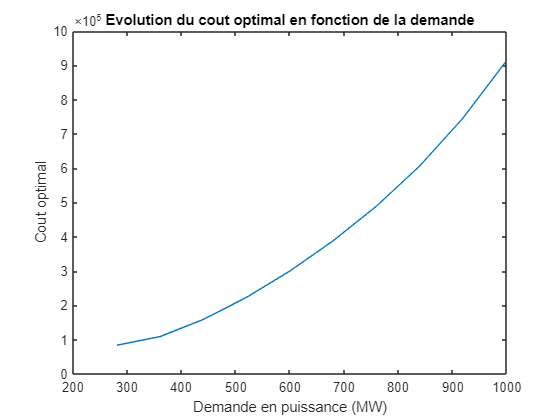

plot(Demande,abs(Cout_opti))
title('Evolution du cout optimal en fonction de la demande')
xlabel('Demande en puissance (MW)')
ylabel('Cout optimal')

*Evolution des puissances de chaque centrale en fonction de la demande*

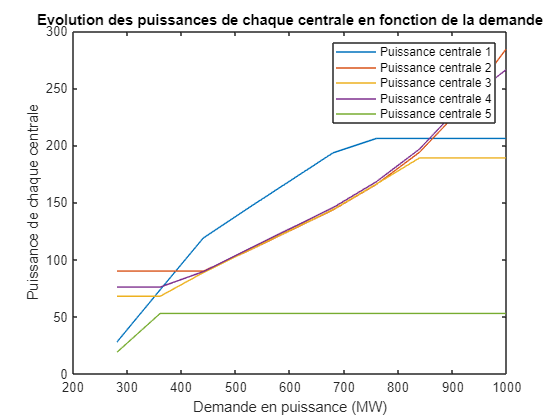

Puissance_1=X_sol(:,1);
Puissance_2=X_sol(:,2);
Puissance_3=X_sol(:,3);
Puissance_4=X_sol(:,4);
Puissance_5=X_sol(:,5);
plot(Demande,Puissance_1,Demande,Puissance_2,Demande,Puissance_3,Demande,Puissance_4,Demande,Puissance_5);
title('Evolution des puissances de chaque centrale en fonction de la demande')
xlabel('Demande en puissance (MW)')
ylabel('Puissance de chaque centrale')
legend('Puissance centrale 1','Puissance centrale 2','Puissance centrale 3','Puissance centrale 4','Puissance centrale 5')

**Calcul Optimum économique pour une demande de 400 MW (en lien avec la partie 2)**

*Cette valeur de la demande servira pour la partie 2, afin de comparer les résultats obtenus d'un point de vue économique et environnemental*

Demande2=400;

f_obj = @(x) (x.^2*A+x*B+sum(C));
Aineq=[];
bineq=[];
Aeq_400 = [1 1 1 1 1];
beq_400 = [Demande2];
lb=Pmin;
ub=Pmax;
x0 = [103 142 94.5 133 26.5];
[x_400,fval_400,flag_400,out_400,lambda_400,grad_400]=fmincon(f_obj,x0,Aineq,bineq,Aeq_400,beq_400,lb,ub,'',options);

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    9.900e+01    5.494e+02
    1      12    2.061105e+05    9.389e+01    3.443e+02    3.790e+01
    2      18    2.039954e+05    9.17

*Affichage de la répartition des productions optimale d'un point de vue écologique*

disp(x_400);

  102.8442   90.0000   76.7303   77.4255   53.0000



*Affichage de la quantité minimale de polluants pour une demande de 400 MW (en kg/h puis en kg/j)*

disp(fval_400);

   1.3146e+05



disp(fval_400*24);

   3.1549e+06



## Partie 2

*Soit D la demande en puissance du client*

Demande2=400;

*Definition de la fonction objectif (Quantité totale de polluante produite) à minimiser*

*Variables :  Puissance produite par chacune des 5 centrales en MW*

f_obj2 = @(z) (z.^2*(D/24)+z*(E/24)+sum(F));

Definition des contraintes

*Contraintes inégalités linéaires*

Aineq=[];
bineq=[];   

*Contraintes égalités linéaires (La somme des puissances produites doit correspondre à D)*

Aeq2 = [1 1 1 1 1];
beq2 = [Demande2];    

*Definition des bornes*

lb=Pmin;
ub=Pmax; 

*Initialisation*

z0 = [103 142 94.5 133 26.5];
options = optimoptions('fmincon','Display','iter','Diagnostics','on');
[z_sol2,fval2,flag,out,lambda,grad]=fmincon(f_obj2,z0,Aineq,bineq,Aeq2,beq2,lb,ub,'',options);    

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(z)(z.^2*(D/24)+z*(E/24)+sum(F))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    6.814161e+03    9.900e+01    2.078e+01
    1      12    4.449298e+03    2.417e+01    1.738e+01    4.205e+01
    2      18    4.432529e+

disp(z_sol2);

   71.6220   90.0000   68.0000  129.7628   40.6152



*Affichage des quantités de polluants pour les optimums économiques et écologiques*

Quantite_polluant_opti=fval2;
Quantite_polluant_sol_eco=f_obj2(x_400);
disp(Quantite_polluant_opti);

   3.6542e+03



disp(Quantite_polluant_sol_eco);

   4.0442e+03



*Affichage des coûts de production pour les optimums économiques et écologiques*

Cout_sol_env=f_obj(z_sol2);
Cout_sol_eco=fval_400;
disp(Cout_sol_env);

   1.4868e+05



disp(Cout_sol_eco);

   1.3146e+05



*Comparaison de la répartition des puissances de chaque centrale pour les optimums économique et écologique*

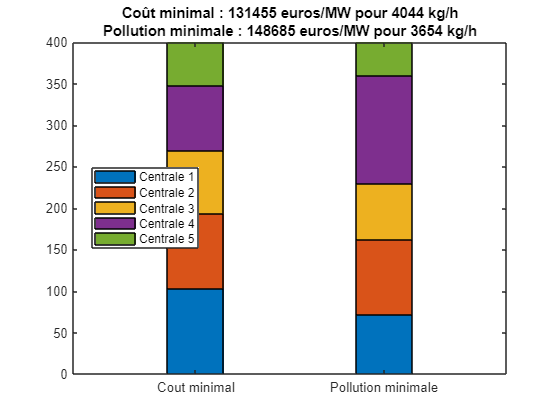

x = categorical([{'Cout minimal'}, {'Pollution minimale'}]);
Optimum_economique = x_400;
Optimum_ecologique = z_sol2;
C1=Cout_sol_eco; Pol1=Quantite_polluant_sol_eco; C2=Cout_sol_env; Pol2=Quantite_polluant_opti;
bar(x,[Optimum_economique;Optimum_ecologique],0.3,'stacked')
legend('Centrale 1','Centrale 2','Centrale 3','Centrale 4','Centrale 5','Location',"best")
title(sprintf('Coût minimal : %3.0f euros/MW pour %4.0f kg/h\nPollution minimale : %3.0f euros/MW pour %4.0f kg/h',...
    C1,Pol1,C2,Pol2))

*Pour une demande constante de 400 MW, on constate que les répartitions de production au sein des centrales ne sont pas les mêmes.*

*Minimiser les coûts revient à maximiser les parts de production des centrales 1, 3 et 5. *

*Minimiser la pollution revient à augmenter la part de production de la centrale 4.*

## Partie 3

## Méthode des e-contraintes

*La première méthode que j'utilise pour optimiser conjointement les composantes environnementales et économiques est celle des e-contraintes. Je cherche à minimiser la fonction coût de production sans dépasser une valeur maximale des rejets de polluants. Le calcul de la quantité de polluants donne une contrainte non linéaire.*

*La valeur maximale correspond à 95 000 kg/j, à partir de laquelle je commence à avoir une pénalité financière.*

Demande3=400;
f_obj = @(x) (x.^2*A+x*B+sum(C));
Aineq=[];
bineq=[];
Aeq_3 = [1 1 1 1 1];
beq_3 = [Demande3];
lb=Pmin;
ub=Pmax;
x0 = [103 142 94.5 133 26.5];
[x_3,fval_3,flag_3,out_3,lambda_3,grad_3]=fmincon(f_obj,x0,Aineq,bineq,Aeq_3,beq_3,lb,ub,@nonlcont,options);

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(x.^2*A+x*B+sum(C))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
Nonlinear constraints:                nonlcont
Nonlinear constraints gradient:       finite-differencing

Constraints
Number of nonlinear inequality constraints: 1
Number of nonlinear equality constraints:   0
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6   

*Répartition des productions de centrale pour une optimisation multicritère*

disp(x_3);

  103.2654   90.0000   72.9907   80.7439   53.0000



*Cout optimisé avec une contrainte sur la quantité de polluant rejetée*

disp(fval_3);

   1.3156e+05



*Pollution pour le coût optimisé*

disp(f_obj2(x_3));

   3.9583e+03



## Méthode de pondération et tracé du front de Pareto

*On décide de tracer un front de Pareto avec un total de 5 valeurs*

nb_front=100;
weight1=linspace(0,1,nb_front);
weight2=linspace(1,0,nb_front);
Liste_solutions=zeros(nb_front,5);
Liste_Cout=zeros(1,nb_front);
Liste_Pollution=zeros(1,nb_front);

for i=1:nb_front
    %Recherche du minimum de F(x)
    w1=weight1(i);
    w2=weight2(i);
    F_obj = @(x) (w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*(D/24)+x*(E/24)+sum(F)));
    Aineq=[];
    bineq=[];
    Aeq_4= [1 1 1 1 1];
    beq_4 = [400];
    lb=Pmin;
    ub=Pmax;
    x0 = [103 142 94.5 133 26.5];
    options = optimoptions('fmincon','Display','iter','Diagnostics','on');
    [x_4,fval_4,flag_4,out_4,lambda_4,grad_4]=fmincon(F_obj,x0,Aineq,bineq,Aeq_4,beq_4,lb,ub,'',options);
    
    Liste_solutions(i,:)=x_4;
    Liste_Cout(i)=f_obj(x_4);
    Liste_Pollution(i)=f_obj2(x_4);
end

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(x)(w1*(x.^2*A+x*B+sum(C))+w2*(x.^2*(D/24)+x*(E/24)+sum(F)))
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    6.814161e+03    9.900e+01    2.078e+01
    1      12    4.449298e+03    2.417e+01    1.738e+01    4.205e+01

**Front de Pareto pour une demande de 400 MW**

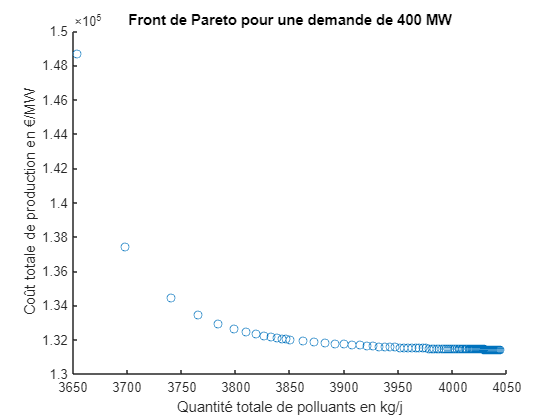

scatter(Liste_Pollution,Liste_Cout);
xlabel('Quantité totale de polluants en kg/j')
ylabel('Coût totale de production en €/MW')
title('Front de Pareto pour une demande de 400 MW')

function [c,ceq]=nonlcont(x,i)
    D=[2;3.82;5.01;1.1;3.55];
    E=[-5;-4.24;-2.15;-3.99;-6.88];
    F=[3;6.09;5.69;6.2;5.57];
    c = (x.^2*(D/24)+x*(E/24)+sum(F))-(95000/24);
    ceq=[];
end

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

*Le front de Pareto nous permet de bien visualiser que la chute importante des coûts de production s'accompagne d'une augmentation de la quantité de polluants rejetée.*

*L'optimum de fonctionnement doit être un juste équilibre entre considérations économiques et environnementales.*

*Je pense que l'optimum de fonctionnement serait plus judicieux avec un valeur limite plus restrictive pour l'émission de polluants (celle ci permettant de plus d'éviter des taxes et pénalités financières).*

*Par exemple, pour une demande de 400 MW, cela pourrait se situer entre les points rejetant 3750 et 3850 kg/j de polluants pour rester dans des coûts de production raisonnables.*